# **Fundamentals of Robotics**

**Introduction to Robotics Modeling and Control**

clear;
close all;
format compact;

## Spatial Mathematics: 3D Translations and Orientations

### Translation and Rotation

### Parameterizations of Rotation Matrix

### Homogenous Matrix Transformation

### EXAMPLE

#### A Robotic Leg: Overview

In this exercise, we are going to analyze the kinematics of a single robot leg with a point foot. Starting with a set of generalized coordinates, we will elaborate relative rotations, translations, and homogeneous transformations. 

The picture below describes a single leg that is attached to a body fixed frame B. This leg has three degrees of freedom consisting of relative rotations about $\alpha$ (alpha) around $_B \mathbf e _x
$, about $\beta$ (beta) around $_1 \mathbf e _y
$, and about $\gamma$ (gamma) around $_2 \mathbf e _y
$. Hence, the generalized coordinates are given by: $\mathbf q := [\alpha \; \beta \; \gamma]^T
$

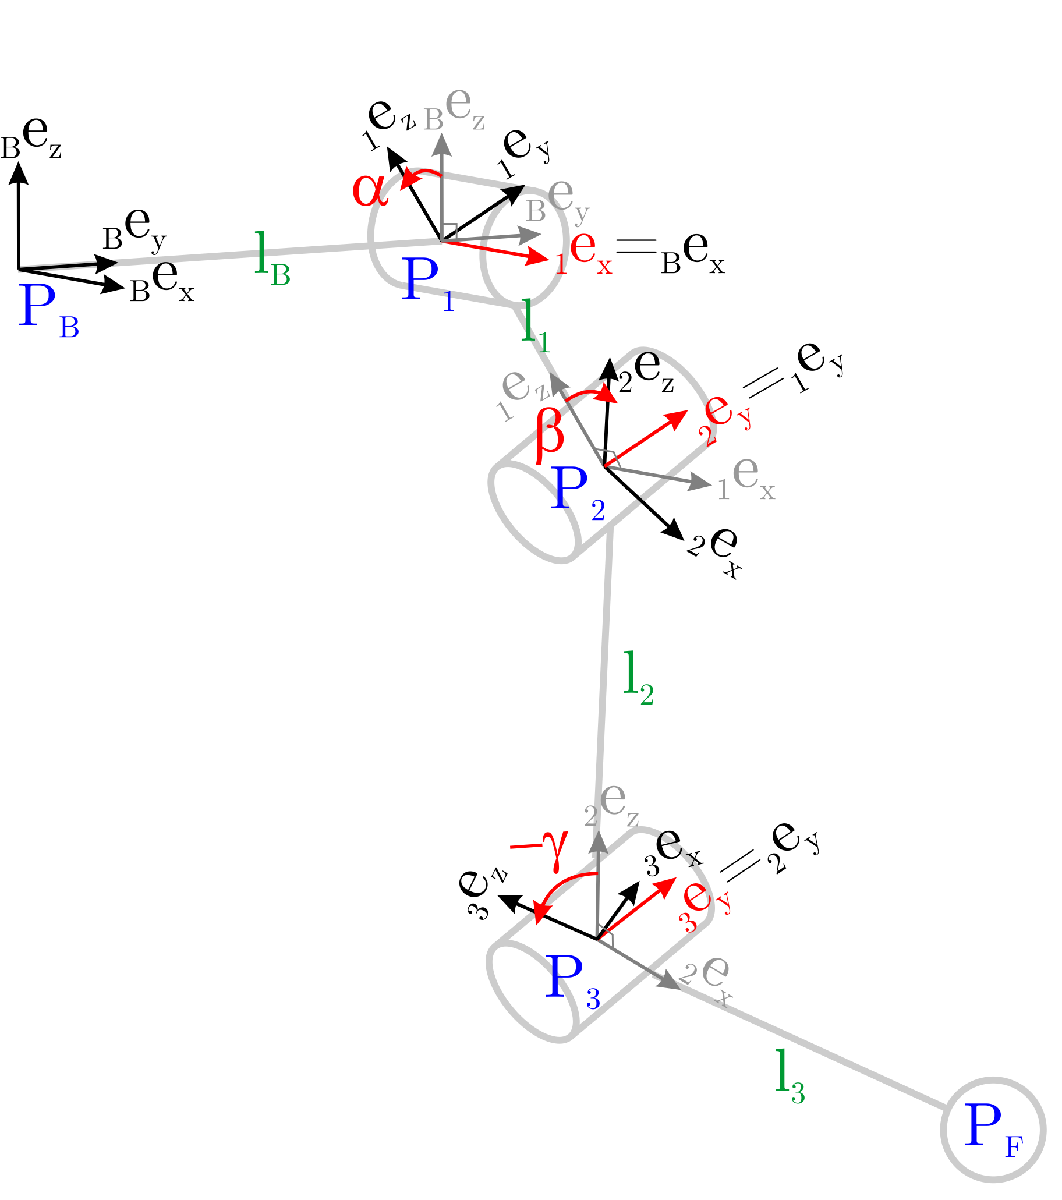

**Resourse:** ETH Autonomous Mobile Robots MOOC

[https://learning.edx.org/course/course-v1:ETHx+AMRx+2T2020/home](https://learning.edx.org/course/course-v1:ETHx+AMRx+2T2020/home)

#### Relative Rotation Matrix

Given the kinematic description of a single leg with three degrees of freedom () we determine the relative rotation matrices  rotating a vector   from an arbitrary coordinate system *C* to *A*:

alpha = sym('alpha','real');
beta = sym('beta','real');
gamma = sym('gamma','real');

% write down the rotation matrices using the symbolic parameters alpha, beta, gamma
R_B1 = [ 1,           0,           0;
         0,  cos(alpha), -sin(alpha);
         0,  sin(alpha),  cos(alpha)];

R_12 = [ cos(-beta),  0, -sin(-beta);
         0,           1,           0;
         sin(-beta),  0,  cos(-beta)];

R_23 = [ cos(-gamma), 0, -sin(-gamma);
         0,           1,            0;
         sin(-gamma), 0,  cos(-gamma)];

#### Homogeneous Transformation

Given the relative rotation matrices from the previous problem and chosing unitary link lengths , we determine the homogeneous transformation   that tranforms the footpoint position represented in coordinate frame 3to coordinate frame *B*:

% links' lenght
lb = 1;
l1 = 1;
l2 = 1;
l3 = 1;

% write down the 3x1 relative position vectors for link length l_i=1
r_B1_inB = [0;  lb;  0];
r_12_in1 = [0;  0; -l1];
r_23_in2 = [0;  0; -l2];
r_3F_in3 = [0;  0; -l3];

% write down the homogeneous transformation matrices
H_B1 = [        R_B1,   r_B1_inB    ;
             0, 0, 0,          1    ];
H_12 = [        R_12,   r_12_in1    ;
             0, 0, 0,          1    ];
H_23 = [        R_23,   r_23_in2    ;
             0, 0, 0,          1    ];
H_3F = [      eye(3),   r_3F_in3    ;
             0, 0, 0,          1    ];

% create the cumulative transformation matrix
H_B2 = H_B1 * H_12;
H_B3 = H_B2 * H_23;
H_BF = H_B3 * H_3F;

% find the foot point position vector
r_BF_inB = H_B3(1:3, :) * [r_3F_in3; 1];

ALPHA =5;
BETA  =-60;
GAMMA =90;

q = [alpha, beta, gamma];
q_conf = deg2rad([ALPHA, BETA, GAMMA]);

H_12 = double( subs(H_12, q, q_conf) );
H_23 = double( subs(H_23, q, q_conf) );
H_3F = double( subs(H_3F, q, q_conf) );

H_B1 = double( subs(H_B1, q, q_conf) );
H_B2 = double( subs(H_B2, q, q_conf) );
H_B3 = double( subs(H_B3, q, q_conf) );

r_BF_inB = double( subs(r_BF_inB, q, q_conf) );
homogtf = {H_B1, H_12, H_23, H_3F};

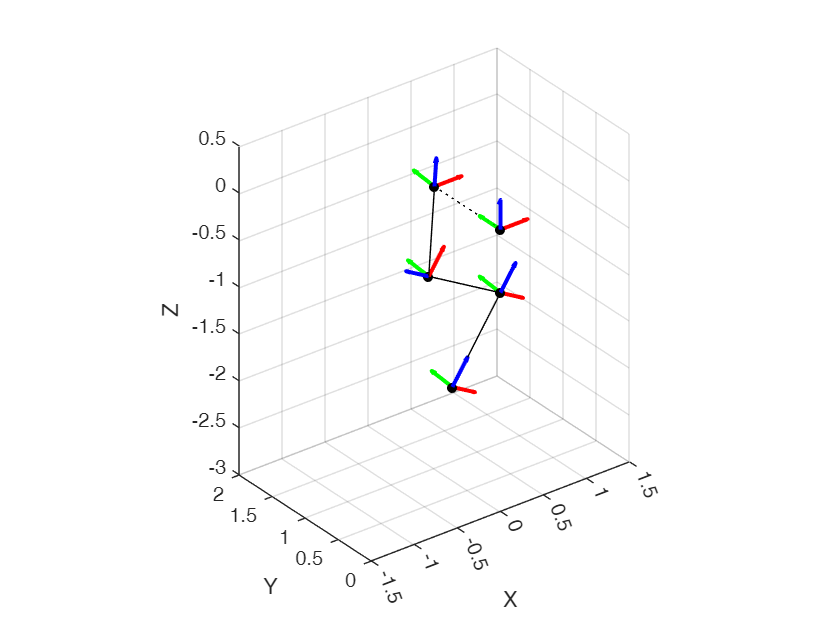

figure;

hold on;
plot3(  [0, H_B1(1,4)], [0, H_B1(2,4)], [0, H_B1(3,4)], 'k:');
plot3(  [H_B1(1,4), H_B2(1,4), H_B3(1,4), r_BF_inB(1)], ...
        [H_B1(2,4), H_B2(2,4), H_B3(2,4), r_BF_inB(2)], ...
        [H_B1(3,4), H_B2(3,4), H_B3(3,4), r_BF_inB(3)], 'k-');
plotHomogFrames(homogtf, 'scale', 0.35, 'ArrowStyle', 'arrow');
hold off;

xticks(-1.5:0.5:1.5);yticks(0:0.5:2);zticks(-3:0.5:0.5);
xlim([-1.5, 1.5]); ylim([0, 2]); zlim([-3, 0.5]);